## **2023AAPS0013P - PID Controller Coded**

**Pranav Chandra N.V**

-----x------x------x------x------x------x------x------x------x------x------x------x------x------

First, we'll set up our main variables, including our transfer function

w = 5; %undamped natural frequency
zeta = 0.5; %zeta value lmao

n = [w^2] %setting an array for our numerator

n = 25

d = [1 2*zeta*w w^2] %setting an array for the denominator

d =      1     5    25



%writing proportional, integral and derivative constants to use
%constants have been pulled from the simulink pid control
Kp = 15.2454925523091;
Ki = 35.4533089526884;
Kd = 1.55694543229371;

%setting up a config file for our step response
Config = RespConfig('Amplitude',10);

Now actually getting our functions

G = tf(n,d) %creating a transfer function using our numerator and denominator

G =
 
        25
  --------------
  s^2 + 5 s + 25
 
Continuous-time transfer function.
Model Properties


C = pid(Kp, Ki, Kd) %generating a PID function

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 15.2, Ki = 35.5, Kd = 1.56
 
Continuous-time PID controller in parallel form.
Model Properties



F = feedback(G*C, 1)

F =
 
     38.92 s^2 + 381.1 s + 886.3
  ---------------------------------
  s^3 + 43.92 s^2 + 406.1 s + 886.3
 
Continuous-time transfer function.
Model Properties


 Graphing

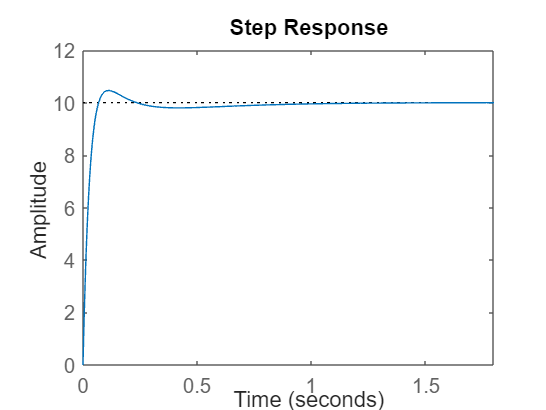

step(F, Config)